# Dynamic Modeling of a Single Heater Using Energy Balance

This live script will teach you how to create a dynamic model of a single heater using energy balance. You will use the TC Lab kit and Simulink to achieve a single heater model.

The main objectives are:

• To apply energy balance to a single heater system and obtain the system dynamics (a differential equation).

• To obtain the transfer function of the system.

• To conduct real-time experiments with the TC Lab kit.

• To use Simulink to simulate the differential equation of the system, and its transfer function, and visualize and compare system response models and real-time experiments.

## **1. A Single Heater Model**

Create a dynamic model for a single heater by employing an energy balance approach. This model should accurately depict the relationship between the input power supplied to the transistor and the temperature measured by a thermistor. It is essential to incorporate both convection and radiation components in the energy balance to ensure a comprehensive representation.

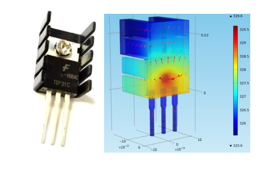

The following equation presents a simplified energy balance for the system, demonstrating how the temperature varies with time.


$$\text{Initial temperature} \ (T_0)
$$



$$\text{Ambient temperature} \ (T_{\infty})
$$



$$\text{Heater output} \ (Q)
$$



$$\text{Heater factor} \ (\alpha)
$$



$$\text{Heat capacity} \ (C_p)
$$



$$\text{Surface Area} \ (A)
$$



$$\text{Mass} \ (m)
$$



$$\text{Overall Heat Transfer Coefficient} \ (U)
$$



$$\text{Emissivity} \ (\epsilon
)
$$



$$\text{Stefan Boltzmann Constant} \ (\sigma)
$$



$$m C_p \frac{d T}{d t} = \sum h_{\text{in}} - \sum h_{\text{out}} + Q
$$



$$mC_p \frac{dT}{dt} = U A (T_{\infty} - T) + \epsilon
 \sigma A (T_{\infty}^4 - T^4) + \alpha Q
$$


## 2. Energy Balance


$$mC_p \frac{dT}{dt} = UA(T_\infty - T) + \epsilon \sigma (T_\infty^4 - T^4) + \alpha Q
$$


Ignoring the radiation components:


$$\ mC_p \frac{dT}{dt} = UA(T_\infty - T) + \alpha Q
$$
      
$$(*)$$


A first-order differential equation is obtained:


$$\frac{mC_p}{UA} \frac{dT}{dt} + T = T_\infty + \frac{1}{UA}\alpha Q
$$


where:

$\tau_p = \frac{mC_p}{UA}
$ , $k_p = \frac{1}{UA}
$

Using Laplace transforms and assuming initial conditions are zero:


$$T(s) = \frac{1}{\tau_p s + 1}T_\infty(s) + \frac{k_p}{\tau_p s + 1} \alpha Q(s)
$$



$$T(s) = T_\infty + \frac{k_p}{\tau_p s + 1} \alpha Q
$$


Using equation (*):


$$\frac{dT}{dt} = \frac{UA(T_\infty - T) + \alpha Q}{mC_p}
$$


The calculation of the system's time constant dependents on the plant parameters, as follows

% Define system parameters
% Mass of the object in kilograms
m = 0.001; % kg (1 gm)
% Overall heat transfer coefficient
U = 200; % W/m^2-K
% Surface area of the object in square meters
A = 2 / 100^2; % m^2
% Specific heat capacity of the object
Cp = 4900.0; % J/kg-K
% Calculate the plant time constant (tau_p)
tau_p = (m*Cp)/(U*A);
disp(['The plant time constant (tau_p) is: ', num2str(tau_p), ' seconds']);

The plant time constant (tau_p) is: 122.5 seconds


## 3. Real-Time Experiments TCLab 

The heater input is 40%. a differential equation that represents the system dynamics is compared to a transfer function model and to the results of the heater real-time response: 

The Simulink Model

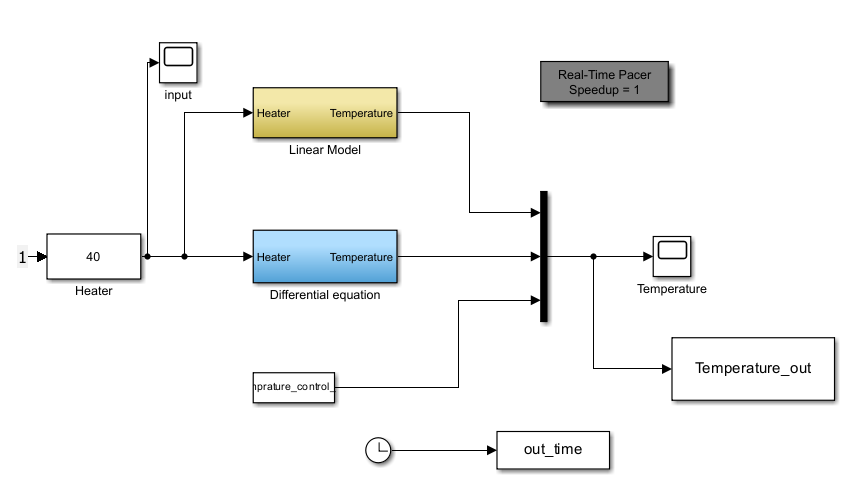

Load experimental data and the initial information to run a simulation for the differential equation and the transfer function model. [Video](https://youtu.be/neEYZS-cKgw) with the real-time experiment

currentpath=pwd;
filename = 'matlab_vid_TClab_dynamics_2023.mat';
fullpath = fullfile(currentpath,filename);
load(fullpath);


t=time';
Temp_nonlin=Temperature(:,3)';
Temprature_control_lab=timeseries(Temp_nonlin,t);

open_system('arduino_lab.slx')
sim('arduino_lab')

arduino_lab/Real-Time Pacer: Average idle real time per major time step = 0.488597 sec



plot(out_time,Temperature_out(:,1),'y')
hold on
plot(out_time,Temperature_out(:,2),'b')
hold on
plot(out_time,Temperature_out(:,3),'r')
xlabel('Time (s)'); 
ylabel('Degree Celsius');
legend('Transfer function', 'Differential equation', 'Experimental response');

## 4. Extra

Work changing the ambient temperature, noise, delay and steady-state gains for the linear model with a transfer function, and for the differential equation to get data closer to the real measured data in red. 